**0. Take a picture with the web-camera.**

Take a picture with the web-camera (Microsoft LifeCam VX-1000, format RGB24_320x240) using the

"Image Acquisition Tool" (parameters: 1 frame, log to memory, 1 trigger and manual) and save it in

Matlab's working memory (Export Data to MATLAB workspace).

Picture = Picture;

size(Picture)

ans =    240   320     3


class(Picture)

ans = 'uint8'


GI = double (rgb2gray (Picture))

GI =    159   160   160   160   160   161   161   161   161   161   161   162   162   162   162   162   161   161   161   160   161   161   155   137   115   115   135   161   174   174   170   168   170   170   170   170   171   171   171   173   172   172   173   173   173   173   174   174   174   176
   159   160   160   161   161   161   161   161   161   161   161   162   162   162   162   162   162   162   162   162   162   162   163   163   157   143   124   117   130   154   171   175   171   170   170   171   173   173   173   173   172   173   173   173   173   174   174   174   176   176
   160   160   161   161   161   161   162   162   162   162   162   162   162   162   163   163   163   163   163   164   164   164   163   163   163   166   166   153   130   114   121   146   169   177   175   171   171   173   173   174   173   173   173   174   174   174   176   176   176   176
   160   160   161   161   161   161   162   162   162   162   163   163   163   163   163  

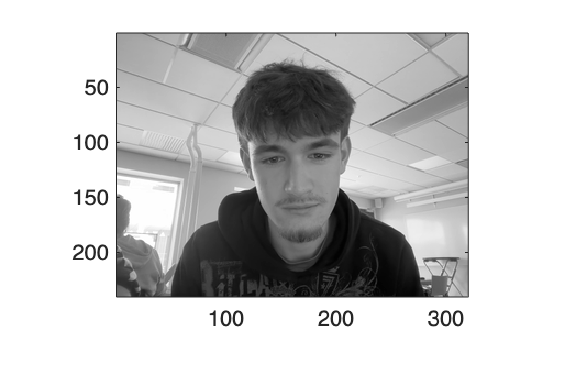

figure (1);
imagesc (GI); 
colormap (gray); 
truesize;

**1. Low-pass filtering.**

Exercise 1.1: Building a low-pass 2D filter

Construct a 2-dimensional Gaussian filter Gxy using Matlab command fspecial (>> help fspecial) and display the filter.

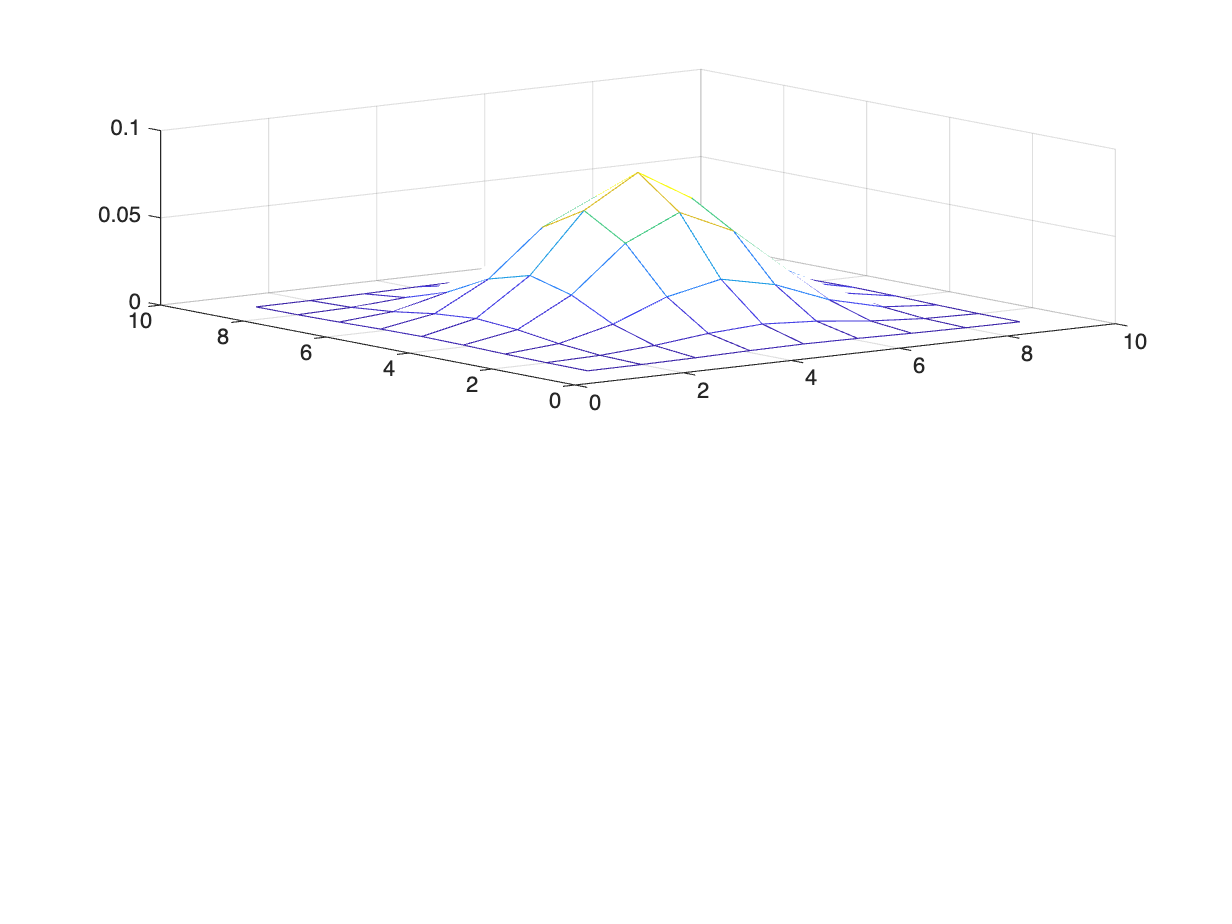

s = 1.4;
hgauss = fspecial("gaussian", 2 * round(3 * s) + 1, s);

figure(2);
subplot(2,1,1); 
mesh(hgauss);

hgauss

hgauss =     0.0000    0.0001    0.0005    0.0011    0.0014    0.0011    0.0005    0.0001    0.0000
    0.0001    0.0008    0.0030    0.0063    0.0082    0.0063    0.0030    0.0008    0.0001
    0.0005    0.0030    0.0106    0.0227    0.0293    0.0227    0.0106    0.0030    0.0005
    0.0011    0.0063    0.0227    0.0489    0.0630    0.0489    0.0227    0.0063    0.0011
    0.0014    0.0082    0.0293    0.0630    0.0814    0.0630    0.0293    0.0082    0.0014
    0.0011    0.0063    0.0227    0.0489    0.0630    0.0489    0.0227    0.0063    0.0011
    0.0005    0.0030    0.0106    0.0227    0.0293    0.0227    0.0106    0.0030    0.0005
    0.0001    0.0008    0.0030    0.0063    0.0082    0.0063    0.0030    0.0008    0.0001
    0.0000    0.0001    0.0005    0.0011    0.0014    0.0011    0.0005    0.0001    0.0000


*What would be the filtered value (output number) of a picture with the constant value 37 in all of its*

*pixels? Figure it out by hand with the scalar product operation (remember that the amount of filter*

*values sum = 1) and check it with Matlab (create an image of the same size as the filter with all values*

*= 37 and calculate the scalar product).*

Apatch = 37 * ones(size(hgauss));

val = sum(hgauss(:) .* Apatch(:));
disp(val)

   37.0000



Exercise 1.2: Building a low-pass 2D filter with two separable 1D filters

Construct two 1-dimensional filters Gx and Gy that arise from the 2-dimensional filter Gxy

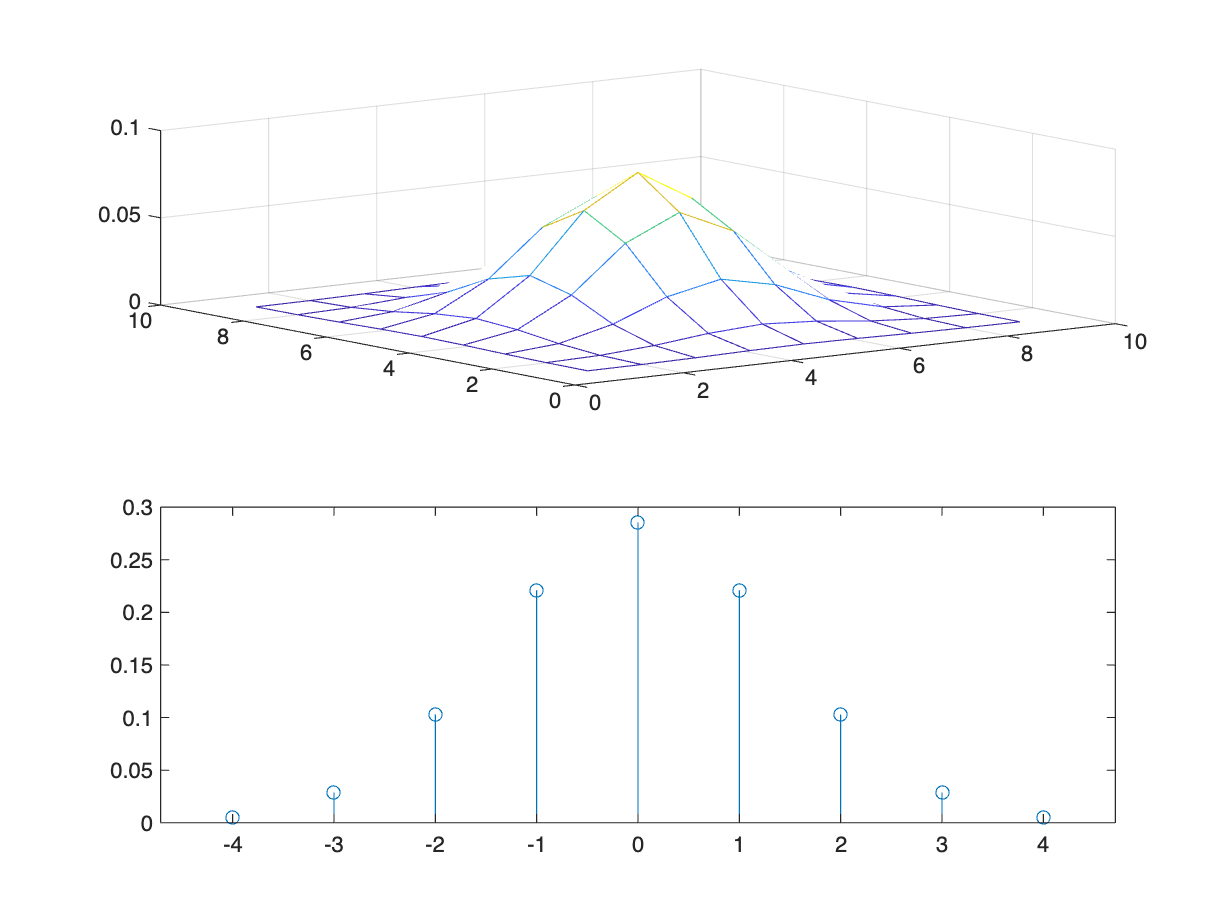

gx=hgauss(5,:); %middle row in the x-direction
gy=hgauss(:,5); %middle column in the y-direction

%make the sum of filter values =1
gx=gx/sum(gx); %gx is the 1-dim filter in the x-direction
gy=gy/sum(gy); % gy is the 1-dim filter in the y-direction
figure(2);
subplot(2,1,2);
stem(-4:4,gx);

gx

gx =     0.0048    0.0287    0.1028    0.2210    0.2853    0.2210    0.1028    0.0287    0.0048


gy

gy =     0.0048
    0.0287
    0.1028
    0.2210
    0.2853
    0.2210
    0.1028
    0.0287
    0.0048


gg = conv2(gx, gy);
gg

gg =     0.0000    0.0001    0.0005    0.0011    0.0014    0.0011    0.0005    0.0001    0.0000
    0.0001    0.0008    0.0030    0.0063    0.0082    0.0063    0.0030    0.0008    0.0001
    0.0005    0.0030    0.0106    0.0227    0.0293    0.0227    0.0106    0.0030    0.0005
    0.0011    0.0063    0.0227    0.0489    0.0630    0.0489    0.0227    0.0063    0.0011
    0.0014    0.0082    0.0293    0.0630    0.0814    0.0630    0.0293    0.0082    0.0014
    0.0011    0.0063    0.0227    0.0489    0.0630    0.0489    0.0227    0.0063    0.0011
    0.0005    0.0030    0.0106    0.0227    0.0293    0.0227    0.0106    0.0030    0.0005
    0.0001    0.0008    0.0030    0.0063    0.0082    0.0063    0.0030    0.0008    0.0001
    0.0000    0.0001    0.0005    0.0011    0.0014    0.0011    0.0005    0.0001    0.0000


hgauss

hgauss =     0.0000    0.0001    0.0005    0.0011    0.0014    0.0011    0.0005    0.0001    0.0000
    0.0001    0.0008    0.0030    0.0063    0.0082    0.0063    0.0030    0.0008    0.0001
    0.0005    0.0030    0.0106    0.0227    0.0293    0.0227    0.0106    0.0030    0.0005
    0.0011    0.0063    0.0227    0.0489    0.0630    0.0489    0.0227    0.0063    0.0011
    0.0014    0.0082    0.0293    0.0630    0.0814    0.0630    0.0293    0.0082    0.0014
    0.0011    0.0063    0.0227    0.0489    0.0630    0.0489    0.0227    0.0063    0.0011
    0.0005    0.0030    0.0106    0.0227    0.0293    0.0227    0.0106    0.0030    0.0005
    0.0001    0.0008    0.0030    0.0063    0.0082    0.0063    0.0030    0.0008    0.0001
    0.0000    0.0001    0.0005    0.0011    0.0014    0.0011    0.0005    0.0001    0.0000


e=hgauss-gg; %error
e2m=sqrt(sum(sum(e.*e)));% square mean error
e2m

e2m = 4.5333e-17

Exercise 1.3: Comparing different filtering methods

Linear filtering can be done in three different ways: convolution with a 2 dimensional filter in the

image plane, convolution with two 1-dimensional filters in the image plane, or multiplication in the

frequency domain). Theoretically, the three methods provide the "same" results!

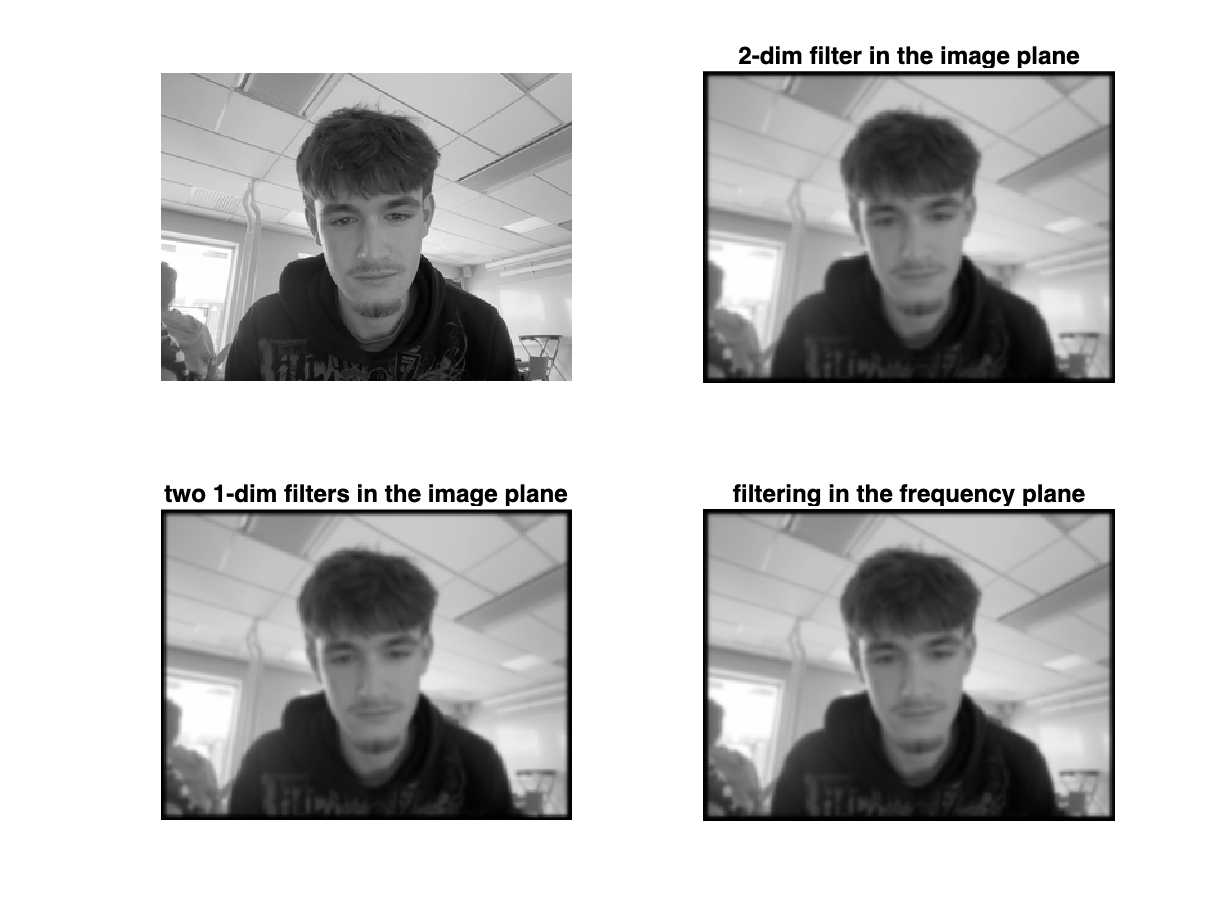

% Filter with 2- dimensional filter in the image plane
y=conv2(GI,hgauss); %filtering by convolution
figure(3);
subplot(2,2,1);imshow(GI/255); %Original image
figure(3); 
subplot(2,2,2); 
imshow(y/255); 
title('2-dim filter in the image plane');

% Filter with two 1- dimensional filters in the image plane
yy=conv2(conv2(GI,gx),gy); % two convolutions with 1-dim filters
figure(3);
subplot(2,2,3); 
imshow(yy/255); 
title('two 1-dim filters in the image plane');

% Filter in the frequency domain according to (Equation 1)
[rf,cf]=size(GI); %image size
[rg,cg]=size(hgauss); %filter size
Nr=rf+rg-1; %number of frequency points in row-direction
Nc=cf+cg-1; % number of frequency points in column-direction
%NOTE! The image and the filter must have the same number of pixels in the frequency domain,
%since filtering is done by pixel-wise multiplication!!
F=fft2(GI,Nr,Nc); %frequency description of the image using the FT
G=fft2(hgauss,Nr,Nc); %frequency description of the filter using the FT
YYY = F.*G; %filtering by pixel-wise multiplication
yyy = real(ifft2(YYY)); %return to the image plane using the IFT
figure(3); 
subplot(2,2,4); 
imshow(yyy/255); title('filtering in the frequency plane');

% Check if the different methods give the same result by calculating the square mean error.
fel1=y-yy; %Difference between 2-dim convolution and two 1-dim convolution
fel2=y-yyy; % Difference between 2-dim convolution and frequency multiplication
kmf1=sum(sum(fel1.*fel1))

kmf1 = 3.6046e-22

kmf2=sum(sum(fel2.*fel2))

kmf2 = 4.0672e-22

*a) How many multiplications per pixel are needed with filtering via hgauss (2-dim filters) and via gx and gy (two 1-dim filters)?*

- *2D: 81 multiplications*

- *2x1D: 18 multiplications*

*b) Do we obtain the same result with the different filtering methods?*

- *Yes*

*c) What is the effect observed in the picture after filtering with Gaussian filters?*

- *Blurring due to the loss of High-Frequencies*

**Exercise 1.4: Increasing the size of the filter**

Increase the size of the Gaussian filter, use now sigma = 2.4 (s = 2.4 in Matlab code of exercise 1.1).

Build a 2-dimensional filter as previously done with Matlab code, and filter the image GI with the new

2-dimensional filter in the image plane. Plot the resulting image.

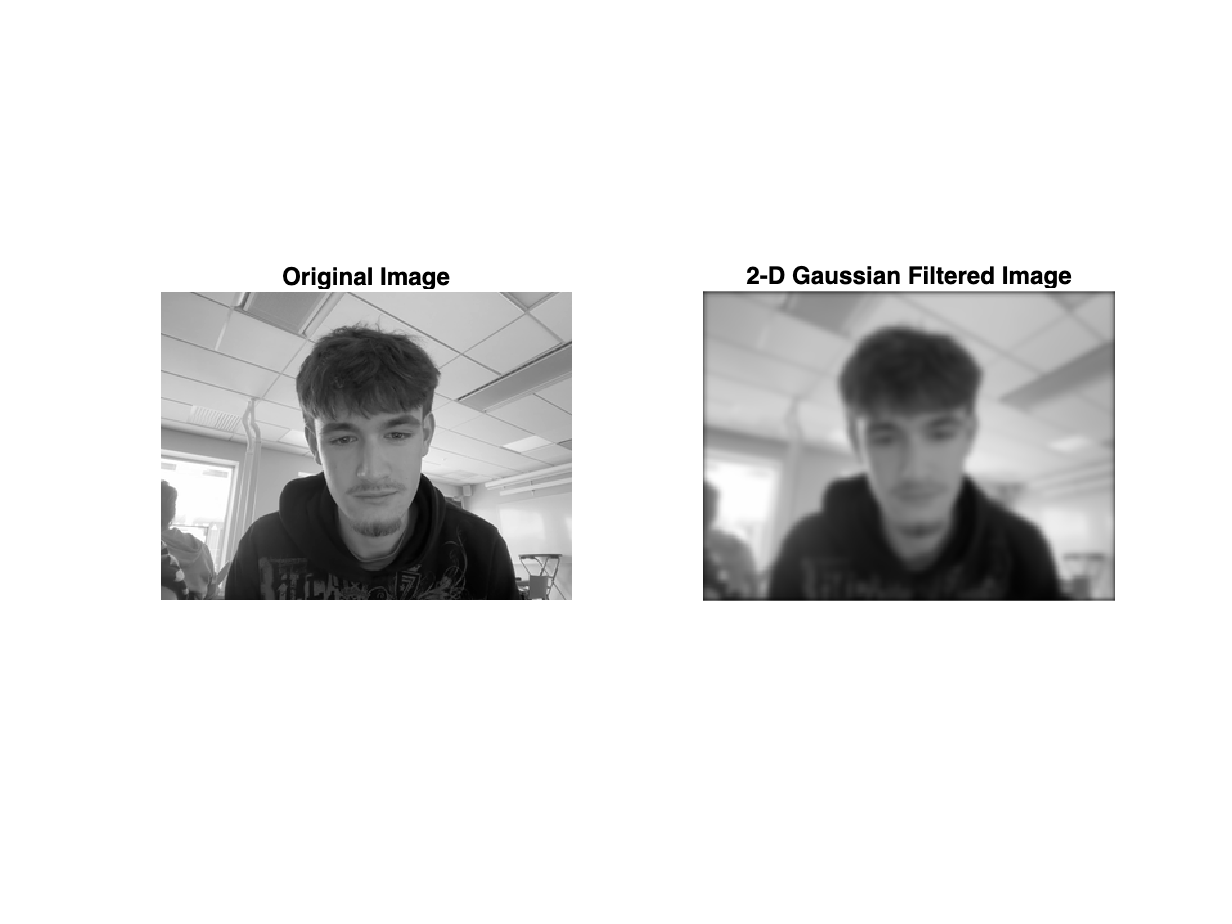

close all;

s_lg = 2.4;
hgauss_lg = fspecial("gaussian", 2 * round(3 * s_lg) + 1, s_lg);

y = conv2(GI, hgauss_lg, 'same'); % use 'same' to keep same image size

figure;
subplot(1,2,1);
imshow(GI/255);
title('Original Image');
grid off;

subplot(1,2,2);
imshow(y/255);
title('2-D Gaussian Filtered Image');
grid off;

hgauss_lg

hgauss_lg =     0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0004    0.0004    0.0004    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000
    0.0000    0.0001    0.0001    0.0003    0.0006    0.0009    0.0011    0.0012    0.0011    0.0009    0.0006    0.0003    0.0001    0.0001    0.0000
    0.0000    0.0001    0.0004    0.0008    0.0014    0.0022    0.0029    0.0032    0.0029    0.0022    0.0014    0.0008    0.0004    0.0001    0.0000
    0.0001    0.0003    0.0008    0.0017    0.0032    0.0049    0.0063    0.0069    0.0063    0.0049    0.0032    0.0017    0.0008    0.0003    0.0001
    0.0002    0.0006    0.0014    0.0032    0.0058    0.0090    0.0116    0.0127    0.0116    0.0090    0.0058    0.0032    0.0014    0.0006    0.0002
    0.0003    0.0009    0.0022    0.0049    0.0090    0.0138    0.0180    0.0196    0.0180    0.0138    0.0090    0.0049    0.0022    0.0009    0.0003
    0.0004    0.0011    0.0029    0.0063    0.0116    0.0180    0.0233    0.0254  

*a) Compare the size of the 2-dimensional Gaussian filters with s = 1.4 and s = 2.4 as a function of the value of s.*

- *1.4: 9x9*

- *2.4: 15x15*

*b) Compare the effect on the image when you use a smaller (s = 1.4) or greater (s = 2.4) filter.*

- *The image is blurrier if we use the larger sigma for the gaussian distribution*

**Exercise 1.5: Noise reduction**

Noise reduction with linear filtering.

Add noise to the image GI and then, filter it with the 2-dimensional filter of s = 2.4. Display both the

noisy image and the filtered image (see earlier MATLAB code to see how you can filter and display a

picture).

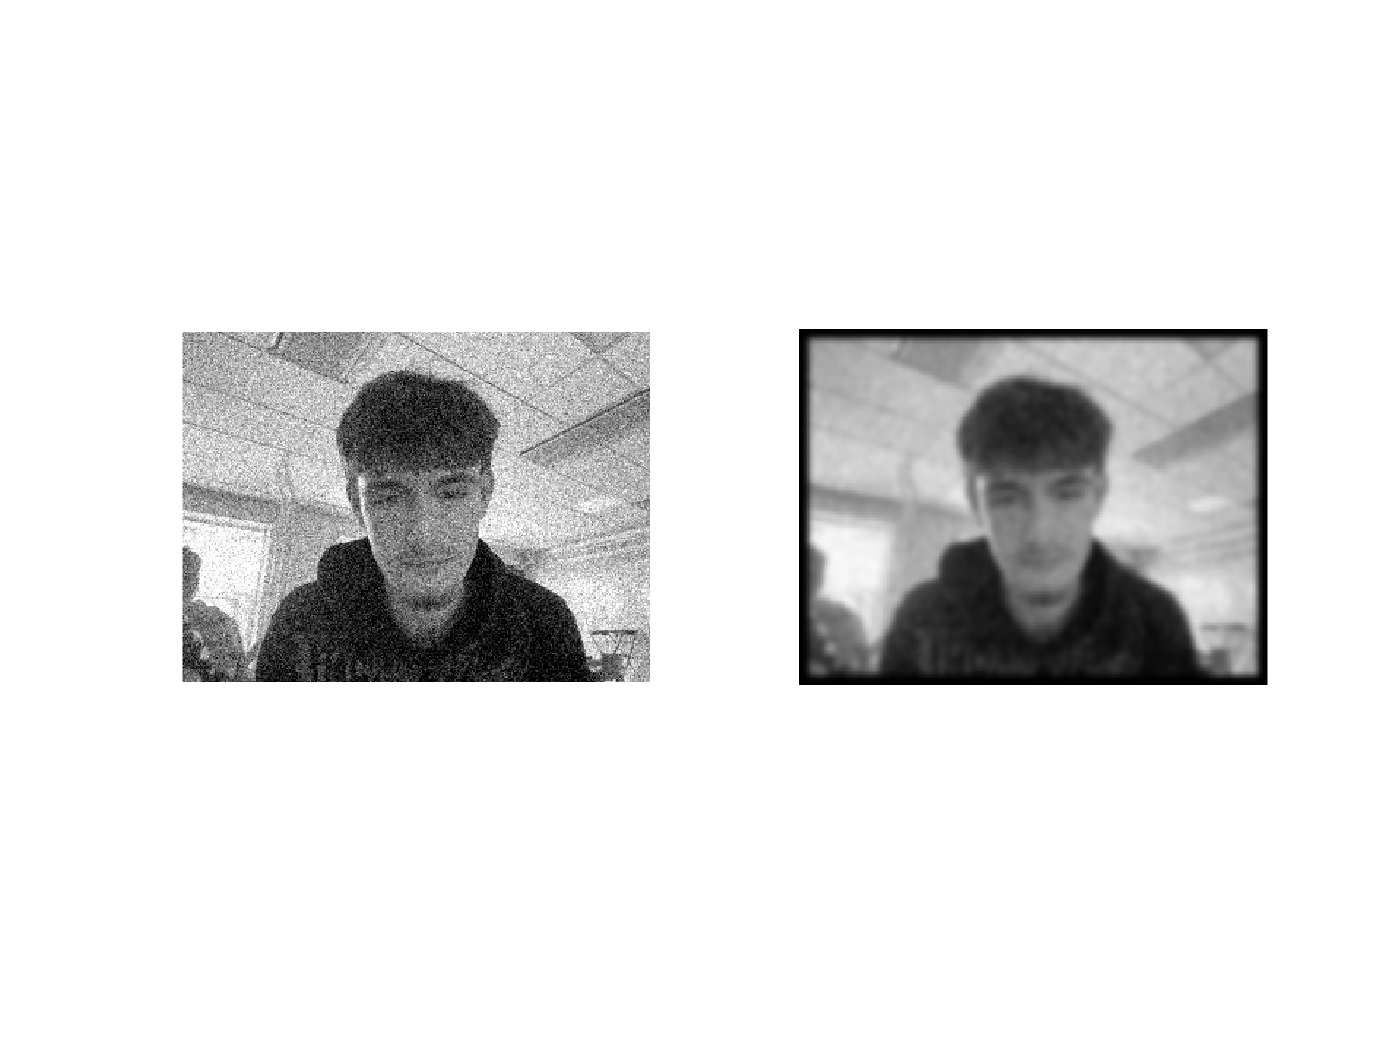

fnoise=imnoise(GI/255,'gaussian',0,0.01).*255;

f_filtered = conv2(fnoise, hgauss_lg);
figure;
subplot(1,2,1);
imshow(fnoise / 255);
subplot(1,2,2);
imshow(f_filtered / 255);

**2. High-pass filtering with derivative filters.**

Exercise 2.1: Building a high-pass 2D filter

Construct 2-dimensional derivative filters (in this exercise we will use a Sobel filter) and display them:

hsobel = fspecial('sobel'); %derivative filter in y-direction
vsobel = hsobel'; %derivative filter in x-direction
hsobel

hsobel =      1     2     1
     0     0     0
    -1    -2    -1


vsobel

vsobel =      1     0    -1
     2     0    -2
     1     0    -1


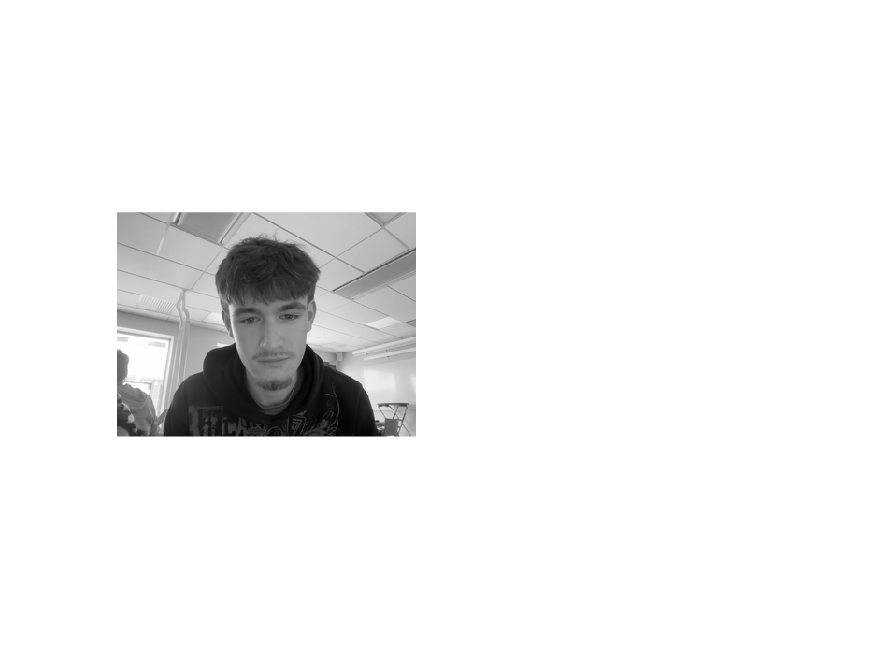

fy=conv2(GI,hsobel);
fx=conv2(GI,vsobel);
figure(5);
imshow(GI/255); %original image

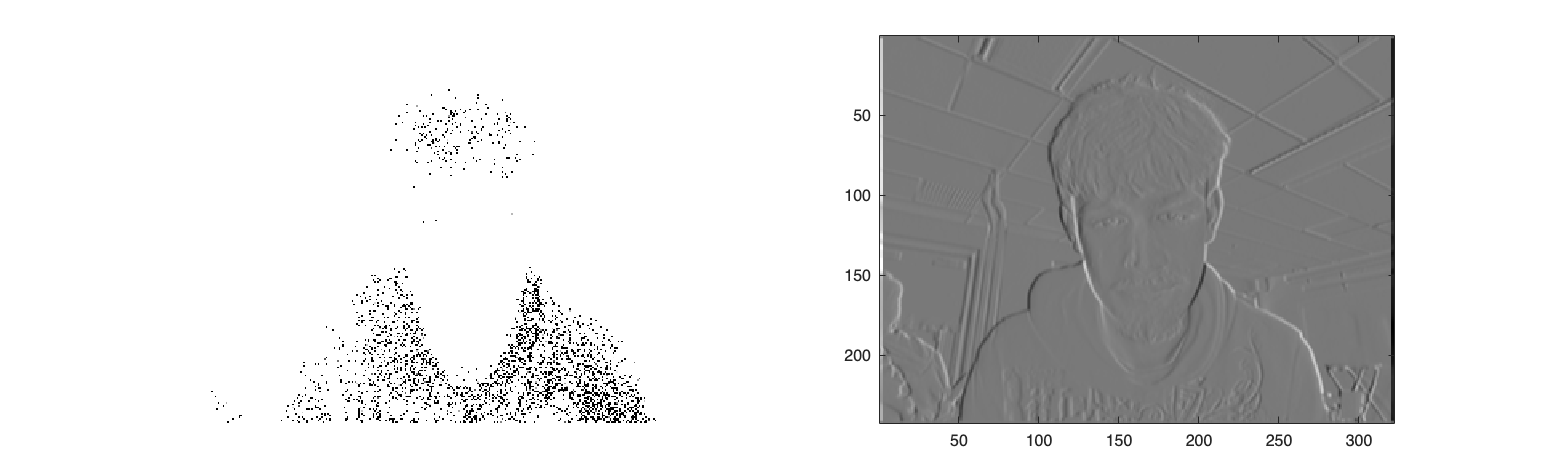

figure(6); 
imagesc(fx); 
colormap(gray); 

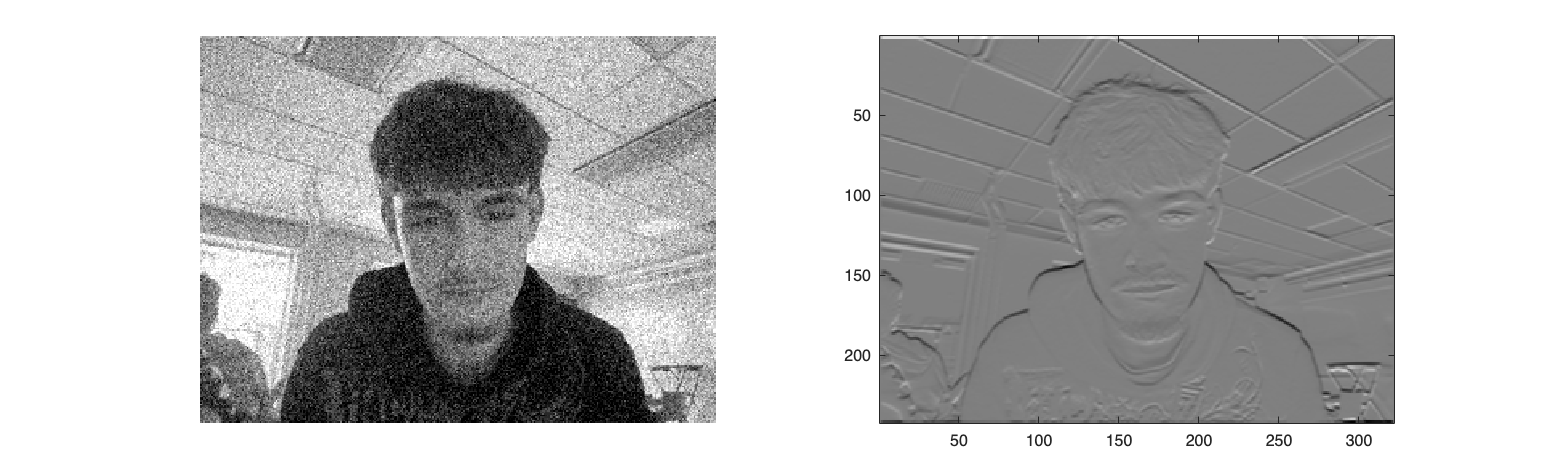

truesize; %derivative in x-direction
figure(7);
imagesc(fy); 
colormap(gray); 

truesize; % derivative in y- direction

*Study the derivative images. Explain the result of the derivation operation in the regions of the image*

*with small variation in grayscale (homogenous areas), and rapid transition from light-to-dark and*

*dark-to-light (edges).*

- *Rapid Transitions (Edges) are detected in a vertical (vsobel) and horizontal (hsobel) manner*

- *Homogenours Areas have a low intesity in the filtered image*

Exercise 2.2: Computing the gradient image

The length of the gradient vector (magnitude) depends on how much grey values change around the

pixel (x,y), and the direction (angle) of the vector is perpendicular to the direction of grey change.

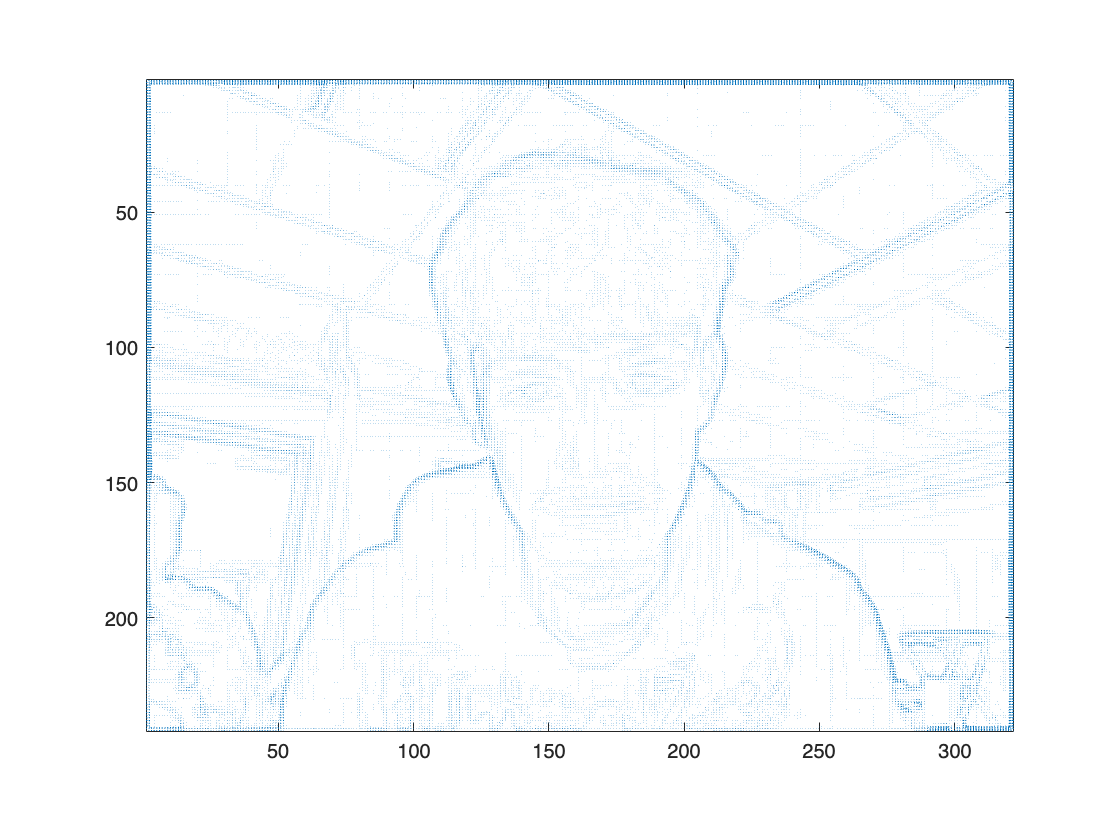

vektorbild=fx+i*fy; %complex gradient
figure(8); 
quiver(real(vektorbild),imag(vektorbild)); axis('ij'); 
axis image;

*How do you interpret the vector (gradient) of a pixel? Give an interpretation of the vector length*

*(magnitude) and its direction (angle). Zoom the image in homogeneous areas and in edges (light-to-*

*dark and dark -to-light) for help with your answer.*

- *Magnitude: intesity of the transition from light to dark (edges)*

- *Direction: direction of the transtion from light to dark*

The magnitude of the gradient (= vector length) is known as the edge image. Calculate the edge image

and display it as follows:

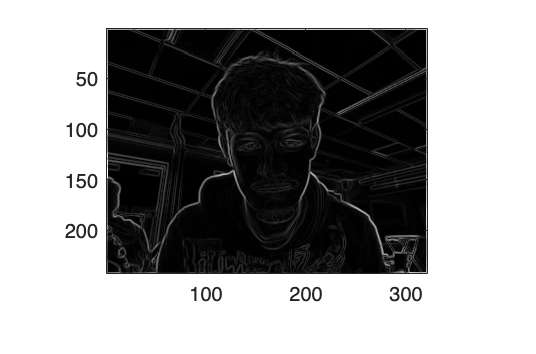

edge=abs(vektorbild); %edge image
figure(9);
imagesc(edge);
colormap(gray); 
truesize;

**Exercise 2.3: Image binarization**

Create a binary image by thresholding the edge image. This will give only those edges that have a

higher value than the value of T (= threshold). To find an appropriate value of T, we use the maximum

value of the edge image

format long g;
max(max(edge)) %obtain the highest value of the edge image

ans =           1022.91945757831


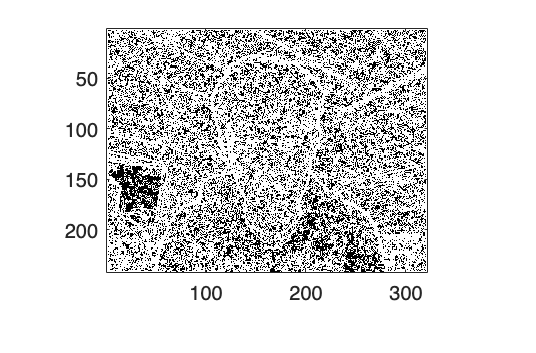

T=80; % threshold value
figure; 
imagesc(edge>T); 
colormap(gray); 
truesize;

- T=80 shows sufficient information to detect imporant contours of the image

Calculate the edge image of the noisy picture fnoise (obtained in exercise 1.5) and display it. Look at

the code above employed in exercises 2.1-2.2 to calculate the edge image of GI without noise, and

modify it appropriately to be applied to fnoise.

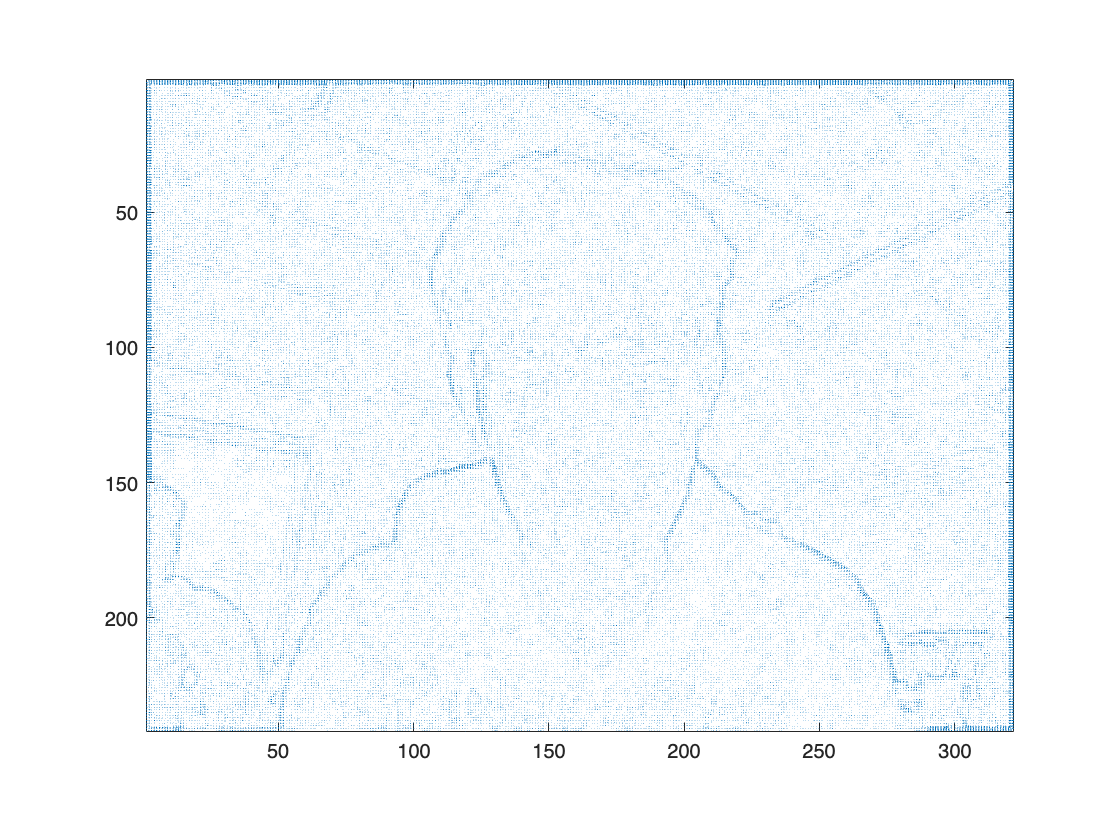

fy=conv2(fnoise,hsobel);
fx=conv2(fnoise,vsobel);
vektorbild=fx+i*fy; %complex gradient

figure; 
quiver(real(vektorbild),imag(vektorbild)); axis('ij'); 
axis image;

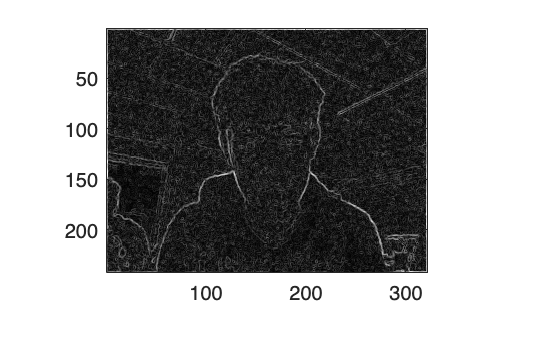

edge=abs(vektorbild); %edge image
figure;
imagesc(edge);
colormap(gray); 
truesize;

format long g;
max(max(edge)) %obtain the highest value of the edge image

ans =           1022.91945757831


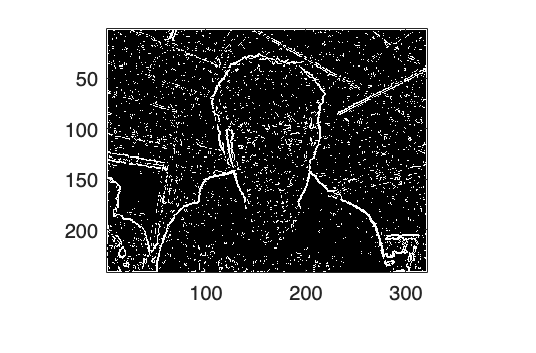

T=220; % threshold value
figure; 
imagesc(edge>T); 
colormap(gray); 
truesize;

- T=220 is a compromise between still detecting important features in the image while introducing some noise in the edge image